%Problem 1
load('Kinematics.mat')


%want to reorganize data so that all observations from the 337 trials are
%put into one large matrix. All the colums refer to a kinematic type
%variable and the rows refer to all the observations taken among trials.

trials = size(Kinematics.Trials, 2);
kinematicTypes = size(Kinematics.ColumnNames, 2);
totalKinematics = [];

for var = 1:kinematicTypes
    combinedKinematics = [];
    
    for i = 1:trials
        currentKinematics = Kinematics.Trials{1, i}(:,var);
        combinedKinematics = vertcat(combinedKinematics, currentKinematics);
    end
    totalKinematics = horzcat(totalKinematics, combinedKinematics);
end

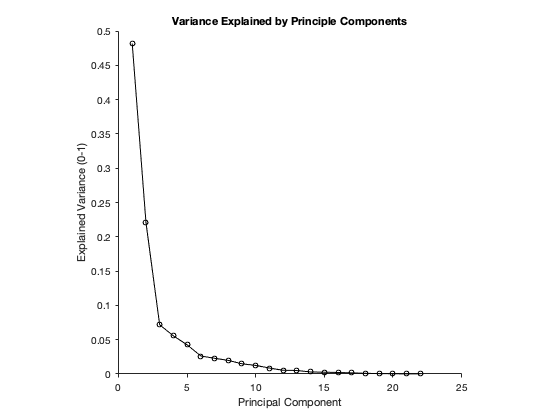

%Part 1
%   A)
[coeff ,score , latent] = pca(totalKinematics);

figure;
hold on;
normalizedLatent = latent./sum(latent);
plot(normalizedLatent,'-ko', 'MarkerSize', 5, 'LineWidth', 1);
axis square;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Principal Component'); 
ylabel('Explained Variance (0-1)');
title('Variance Explained by Principle Components');
hold off;

pcOneExplained = latent(1) / sum(latent);
pcOneTwoExplained = (latent(1) + latent(2)) / sum(latent);
pcOneTwoThreeExplained = (latent(1) + latent(2) + latent(3)) / sum(latent);

%First PC explains 48.18% of the total variance
%First two PCs explain 70.28%
%First three PCs explain 77.45%

%The first 7 PCs are necessary to account for 90% of the overall varaince


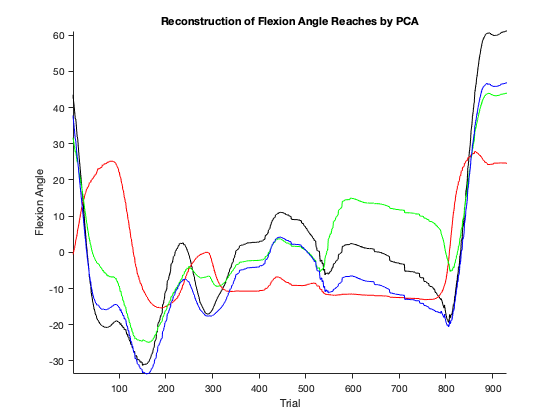

%Part 1
%   B)

%The original wrist flexion data for the first trial
trialOneWristFlexion = Kinematics.Trials{1, 1}(:,3); %totalKinematics(1:931, 3);

%Get cummulative pc transformations from the first three pc components and
%the third variable coefficent (wrist_flexion_1) from the original data matrix
transformedPC1WristFlexion = score(1:931, 1) * coeff(3,1);
transformedPC2WristFlexion = (score(1:931, 2) * coeff(3,2)) + transformedPC1WristFlexion;
transformedPC3WristFlexion = (score(1:931, 3) * coeff(3,3)) + transformedPC2WristFlexion;

transformedAllPCWristFlexion = zeros(931,1);
for k = 1:kinematicTypes 
    transformedAllPCWristFlexion = transformedAllPCWristFlexion + score(1:931, k) * coeff(3,k);
end

figure;
hold on;
plot(trialOneWristFlexion, 'k');
plot(transformedPC1WristFlexion, 'r');
plot(transformedPC2WristFlexion, 'g');
plot(transformedPC3WristFlexion, 'b');
%plot(transformedAllPCWristFlexion);
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Trial'); 
ylabel('Flexion Angle');
title('Reconstruction of Flexion Angle Reaches by PCA');
hold off;

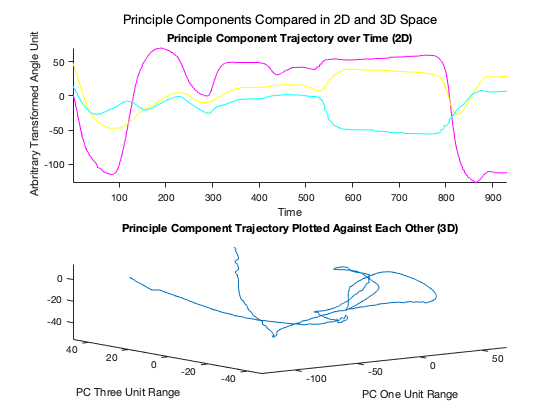

%Part 1
%   C)

%Get the data from the first, second, and third pc components for the first
%trial
pcOneTrialOne = score(1:931,1);
pcTwoTrialOne = score(1:931,2);
pcThreeTrialOne = score(1:931,3);

% Used to observe lower variance principle components
% pcOneTrialOne = score(1:931,20);
% pcTwoTrialOne = score(1:931,21);
% pcThreeTrialOne = score(1:931,22);

subplot(2, 1, 1)
hold on;
plot(pcOneTrialOne, 'm');
plot(pcTwoTrialOne, 'y');
plot(pcThreeTrialOne, 'c');
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('Time'); 
ylabel(' Arbritrary Transformed Angle Unit');
title('Principle Component Trajectory over Time (2D)');
hold off;

subplot(2, 1, 2)
plot3(pcOneTrialOne, pcTwoTrialOne, pcThreeTrialOne);
set(gca, 'TickDir', 'out', 'Box', 'off');
axis tight;
xlabel('PC One Unit Range'); 
ylabel('PC Two Unit Range');
ylabel('PC Three Unit Range');
title('Principle Component Trajectory Plotted Against Each Other (3D)');

sgtitle('Principle Components Compared in 2D and 3D Space');


%The projection amplitudes of principal components with less variance
%appear to be much smaller than the highest variance principle components.
%The three lowest variance components only seem to really have an amplitude
%ranging from 2 to -2 (compare to 50 to -100 in the highest varaince components). 
% The frequency of these projections also seems to begreater than the highest 
% variance projections. There appear to be many peaks and troughs throughout 
% the trial timespan whereas the high variance components only seemed to have 
% 1 or 2 sections in there projections where there was a large increase or decrease 
% in their projection amplitude. The projections of the low variance PCs
% overall have a more jagged look to them and seem to be more sporadic and
% less informative in the way they capture the flexion data.

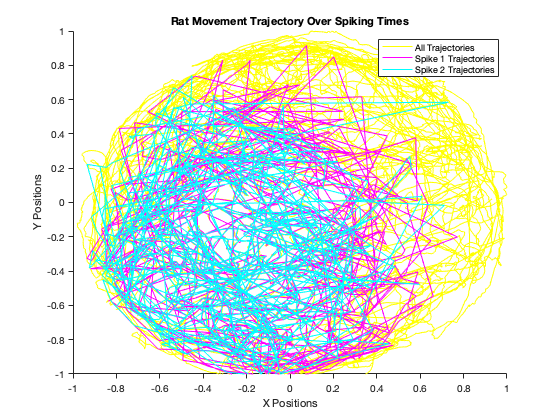

%Part 
%   A)
load('hipp_data.mat')

%Get timesteps fro all the recordings and vertically concatenate to the
%position data
bins = 0:0.001:41.327;
bins = bins';

%Make large array of all the movements and spiking times and separate all
%movements where neuron 1 and neuron 2 spiked
allTrajectories = [bins spikes spikes2 xN yN];
allSpikesOne = find(allTrajectories(:,2)==1);
oneTrajectories = allTrajectories(allSpikesOne,:);
allSpikesTwo= find(allTrajectories(:,3)==1);
twoTrajectories = allTrajectories(allSpikesTwo,:);

figure;
hold on;
plot(allTrajectories(:,4), allTrajectories(:,5), 'y');
plot(oneTrajectories(:,4), oneTrajectories(:,5), 'm');
plot(twoTrajectories(:,4), twoTrajectories(:,5), 'c');
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('X Positions'); 
ylabel('Y Positions');
xlim([-1 1]);
ylim([-1 1]);
title('Rat Movement Trajectory Over Spiking Times');
legend('All Trajectories','Spike 1 Trajectories','Spike 2 Trajectories');
hold off;


%It is hard to get much information distinguishing how the neurons fire
%relative to spatial properities as they are very overlapped. The first
%neuron seems to have more spikes towards the positive extremes of the X
%and Y positions though, since its spiking activity seems to be more dense 
%around X and Y positions 0.4-0.7 than the second neuron's spiking activity
%in those ranges. Both neurons also seem to show some sparse firing
%activity round X = -0.3 and Y = 0 - -0.2.

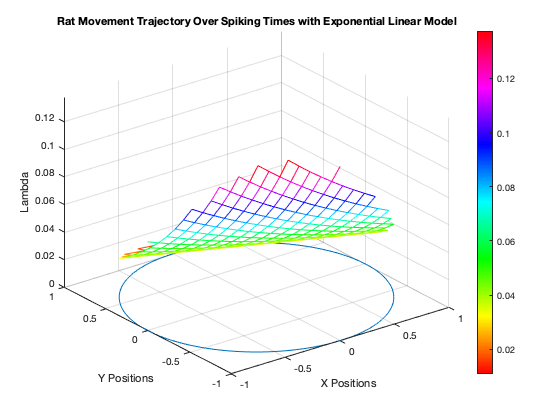

%Part 2
%   B)
%used provided hipp_glm function

[b,dev,stats] = glmfit([xN yN],spikes,'poisson');

%visualize your model
% construct a grid of positions to plot the model against...
figure;
[x_new,y_new]=meshgrid(-1:.1:1);

% compute lambda for each point on this grid using the GLM model
lambda = exp( b(1) + b(2)*x_new + b(3)*y_new );
lambda(find(x_new.^2+y_new.^2>1))=nan;

%plot lambda as a function of position over this grid
h_mesh = mesh(x_new,y_new,lambda,'AlphaData',0);
hold on;
plot3(cos(-pi:1e-2:pi),sin(-pi:1e-2:pi),zeros(size(-pi:1e-2:pi)));
xlim([-1 1]);
ylim([-1 1]);
colormap('hsv');
colorbar;
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('X Positions'); 
ylabel('Y Positions');
zlabel('Lambda');
title('Rat Movement Trajectory Over Spiking Times with Exponential Linear Model');
hold off;


% The three parameter estimate p-vlaues are 0, 8.48174107673636e-27,
% 3.85239644930729e-153; which are all much less than 0.05 or 0.01. So we can
% reject the null hypothesis of there being no meaningful realtionship of
% the estimates; parameter estimates are significant. 

%It provides a clearer description of neuron firing densitys at some
%locations but it is still somewhat difficult to see the exact locality of where 
%the specific neurons fired. It looks like there was a generally high
%amount of firing in the X = -0.5 Y = -1 region, but as it curves back
%towards the positive X and Y locations, this descriptor is less obvious.
%So this model struggles to fully capture the spatial firing properties of the neurons,
%although the X and Y positions are more clearly separated. 

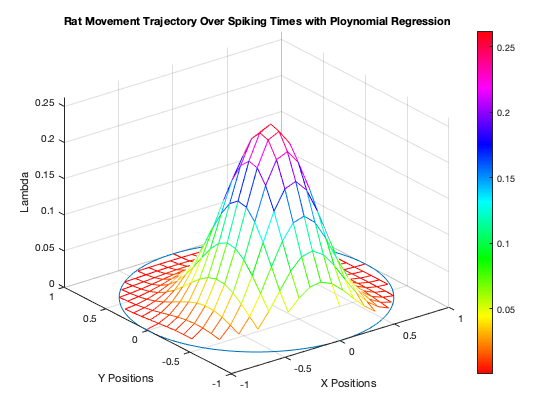



[bQuad,devQuad,statsQuad] = glmfit([xN yN xN.^2 yN.^2],spikes,'poisson');

figure;
[xNewQuad,yNewQuad]=meshgrid(-1:.1:1);

% compute lambda for each point on this grid using the GLM model
lambdaQuad = exp( bQuad(1) + bQuad(2)*xNewQuad + bQuad(3)*yNewQuad + bQuad(4)*xNewQuad.^2 + bQuad(5)*yNewQuad.^2);
lambdaQuad(find(x_new.^2+y_new.^2>1))=nan;

%plot lambda as a function of position over this grid
h_mesh = mesh(xNewQuad,yNewQuad,lambdaQuad,'AlphaData',0);
hold on;
plot3(cos(-pi:1e-2:pi),sin(-pi:1e-2:pi),zeros(size(-pi:1e-2:pi)));
colormap('hsv');
colorbar;
axis tight;
set(gca, 'TickDir', 'out', 'Box', 'off');
xlabel('X Positions'); 
ylabel('Y Positions');
zlabel('Lambda');

xlim([-1 1]);
ylim([-1 1]);
title('Rat Movement Trajectory Over Spiking Times with Ploynomial Regression');
hold off;



% The three parameter estimate p-vlaues are 0, 1.51920822501330e-56, 7.94099857037239e-141,
% 7.65318362933714e-190, and2.73779800788127e-163; which are all significantly  less than 0.05 
% or 0.01 and still definitely sufficent in rejecting the null hypothesis of the maximum
% likelihood estimates not being significant.

%This model most clearly shows the location at which firing likelihood density is
%the highest as a result of the loaction. It is clearly shown the exact X Y locality space 
%where firing should mose be expected, in or slightly positive of the
%center for the X and Y postions. This shows the most clear separations and
%distinctions among the X and Y psitions realtive to their firing
%likelihood.


Part 1
load('mazeJ0916Reduced.mat')


%get bin counts for every trial and their respective measured neuron units.
%Want to measure offset of neurons from 100 ms before movement to 400
%ms after

%   A)

bins = 100:10:400;
binCenters = (bins(1:end-1) + bins(2:end)) / 2;
timeBins = length(binCenters);

units = size(R(1).unit, 2);

uniqueConditions = unique([R.conditionID]');
totalConditions = size(uniqueConditions, 1);

justSpikes16 = zeros(30,28,199);
justSpikes25 = zeros(30,30,199);


for conditionNum = 1:totalConditions
    
    currentCondition = uniqueConditions(conditionNum);
    conditionData = R([R.conditionID] == 16);
    currentConditionSize = size(conditionData, 2);
    
    for conditionTrialIndex = 1:currentConditionSize
        
        conditionTrialOnsetTime = conditionData(conditionTrialIndex).targetAppearsTime;
        conditionSpikesPerBin = [];
        
        for conditionUnitNum = 1:units
            
            conditionSpikesRelativeToMove = conditionData(conditionTrialIndex).unit(conditionUnitNum).spikeTimes - conditionTrialOnsetTime;
            conditionSpikesPerBin =  histcounts(conditionSpikesRelativeToMove, bins);
            
            if currentCondition == 16
            justSpikes16(:, conditionTrialIndex,conditionUnitNum) = conditionSpikesPerBin';
            end
            if currentCondition == 25
            justSpikes25(:, conditionTrialIndex,conditionUnitNum) = conditionSpikesPerBin';
            end

        end

        
    end
    
end

%   B)
%trial average spike counts and convert to spikes/s
avgjustSpikes16 = mean(mean(justSpikes16, 2), 1) * 1000;
avgjustSpikes25 = mean(mean(justSpikes25, 2), 1) * 1000;

combinedData = vertcat(avgjustSpikes16, avgjustSpikes25);

condtionDifferenced = abs(binAveragedData(1,:,:) - binAveragedData(2,:,:));


%   C)
%find difference between spike rate in condition 1 and condition 2 neurons
%to find tuned units
tunedUnits = find(condtionDifferenced(condtionDifferenced(:) >= 19.999));
tunedSize = size(tunedUnits, 1);
